# 深層学習モデルの作成と学習

次のプロパティを使って深層学習ネットワークを作成し学習させるためのスクリプト:

このスクリプトを実行してネットワーク層を作成し、学習データと検証データをインポートし、ネットワークに学習させます。ネットワーク層はワークスペース変数 `layers` に保存されています。学習済みネットワークはワークスペース変数 `net` に保存されています。

詳細については [ディープ ネットワーク デザイナーから MATLAB コードを生成](matlab:helpview('deeplearning','generate_matlab_code')) を参照してください。

MATLAB からの自動生成日: 2022/09/22 14:18:52

## 初期パラメーターの読み込み

ネットワーク初期化のためのパラメーターを読み込みます。転移学習では、ネットワークの初期化パラメーターは初期事前学習済みネットワークのパラメーターです。

trainingSetup = load("C:\研究(ロボットマニピュレータ)\MATLAB_研究\高橋_MATLAB\転移学習_VGG16\VGG16_matlab\params_2022_09_22__14_18_40.mat");

## データのインポート

学習データと検証データをインポートします。

imdsTrain = imageDatastore("C:\研究(ロボットマニピュレータ)\MATLAB_研究\高橋_MATLAB\転移学習_VGG16\ChangemyImages","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## 拡張の設定

imageAugmenter = imageDataAugmenter(...
    "RandRotation",[-90 90]);

% ネットワークの入力層と一致するようにイメージのサイズを変更します。
augimdsTrain = augmentedImageDatastore([224 224 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([224 224 3],imdsValidation);

## 学習オプションの設定

学習の際に使用されるオプションを指定します。

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.001,...
    "MaxEpochs",20,...
    "MiniBatchSize",64,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## 層の配列の作成

layers = [
    imageInputLayer([224 224 3],"Name","input","Mean",trainingSetup.input.Mean)
    convolution2dLayer([3 3],64,"Name","conv1_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv1_1.Bias,"Weights",trainingSetup.conv1_1.Weights)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],64,"Name","conv1_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv1_2.Bias,"Weights",trainingSetup.conv1_2.Weights)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv2_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv2_1.Bias,"Weights",trainingSetup.conv2_1.Weights)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],128,"Name","conv2_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv2_2.Bias,"Weights",trainingSetup.conv2_2.Weights)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv3_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv3_1.Bias,"Weights",trainingSetup.conv3_1.Weights)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],256,"Name","conv3_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv3_2.Bias,"Weights",trainingSetup.conv3_2.Weights)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],256,"Name","conv3_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv3_3.Bias,"Weights",trainingSetup.conv3_3.Weights)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv4_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv4_1.Bias,"Weights",trainingSetup.conv4_1.Weights)
    reluLayer("Name","relu4_1")
    convolution2dLayer([3 3],512,"Name","conv4_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv4_2.Bias,"Weights",trainingSetup.conv4_2.Weights)
    reluLayer("Name","relu4_2")
    convolution2dLayer([3 3],512,"Name","conv4_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv4_3.Bias,"Weights",trainingSetup.conv4_3.Weights)
    reluLayer("Name","relu4_3")
    maxPooling2dLayer([2 2],"Name","pool4","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv5_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv5_1.Bias,"Weights",trainingSetup.conv5_1.Weights)
    reluLayer("Name","relu5_1")
    convolution2dLayer([3 3],512,"Name","conv5_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv5_2.Bias,"Weights",trainingSetup.conv5_2.Weights)
    reluLayer("Name","relu5_2")
    convolution2dLayer([3 3],512,"Name","conv5_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",trainingSetup.conv5_3.Bias,"Weights",trainingSetup.conv5_3.Weights)
    reluLayer("Name","relu5_3")
    maxPooling2dLayer([2 2],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","WeightL2Factor",0,"Bias",trainingSetup.fc6.Bias,"Weights",trainingSetup.fc6.Weights)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","WeightL2Factor",0,"Bias",trainingSetup.fc7.Bias,"Weights",trainingSetup.fc7.Weights)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(6,"Name","fc")
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## ネットワークの学習

指定したオプションと学習データを使用してネットワークを学習させます。

単一の CPU で学習中。
入力データの正規化を初期化しています。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチの精度　　｜　　検証精度　　｜　　ミニバッチ損失　　｜　　検証損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０１：０７　｜　　　　　１８．７５％　｜　　９．５２％　｜　　　　４．０７０７　｜　２．１３２７　｜　　０．００１０　｜
｜　　　　　　５　｜　　　　５　｜　　　　　００：０５：２７　｜　　　　　２６．５６％　｜　４５．２４％　｜　　　　１．９０６０　｜　１．４３１６　｜　　０．００１０　｜
｜　　　　　１０　｜　　　１０　｜　　　　　００：１０：５０　｜　　　　　５４．６９％　｜　７１．４３％　｜　　　　１．１９８１　｜　０．９９９３　｜　　０．００１０　｜
｜　　　　　１５　｜　　　１５　｜　　　　　００：１６：１２　｜　　　　　８２．８１％　｜　８５．７１％　｜　　　　０．６２４９　｜　０．５２３７　｜　　０．００１０　｜
｜　　　　　２０　｜　　　２０　｜　　　　　００：２１：２６　｜　　　　　８９．０６％　｜　９５．２４％　｜　　　　０．３４２８　｜　０．２３８１　｜　　０．００１０　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


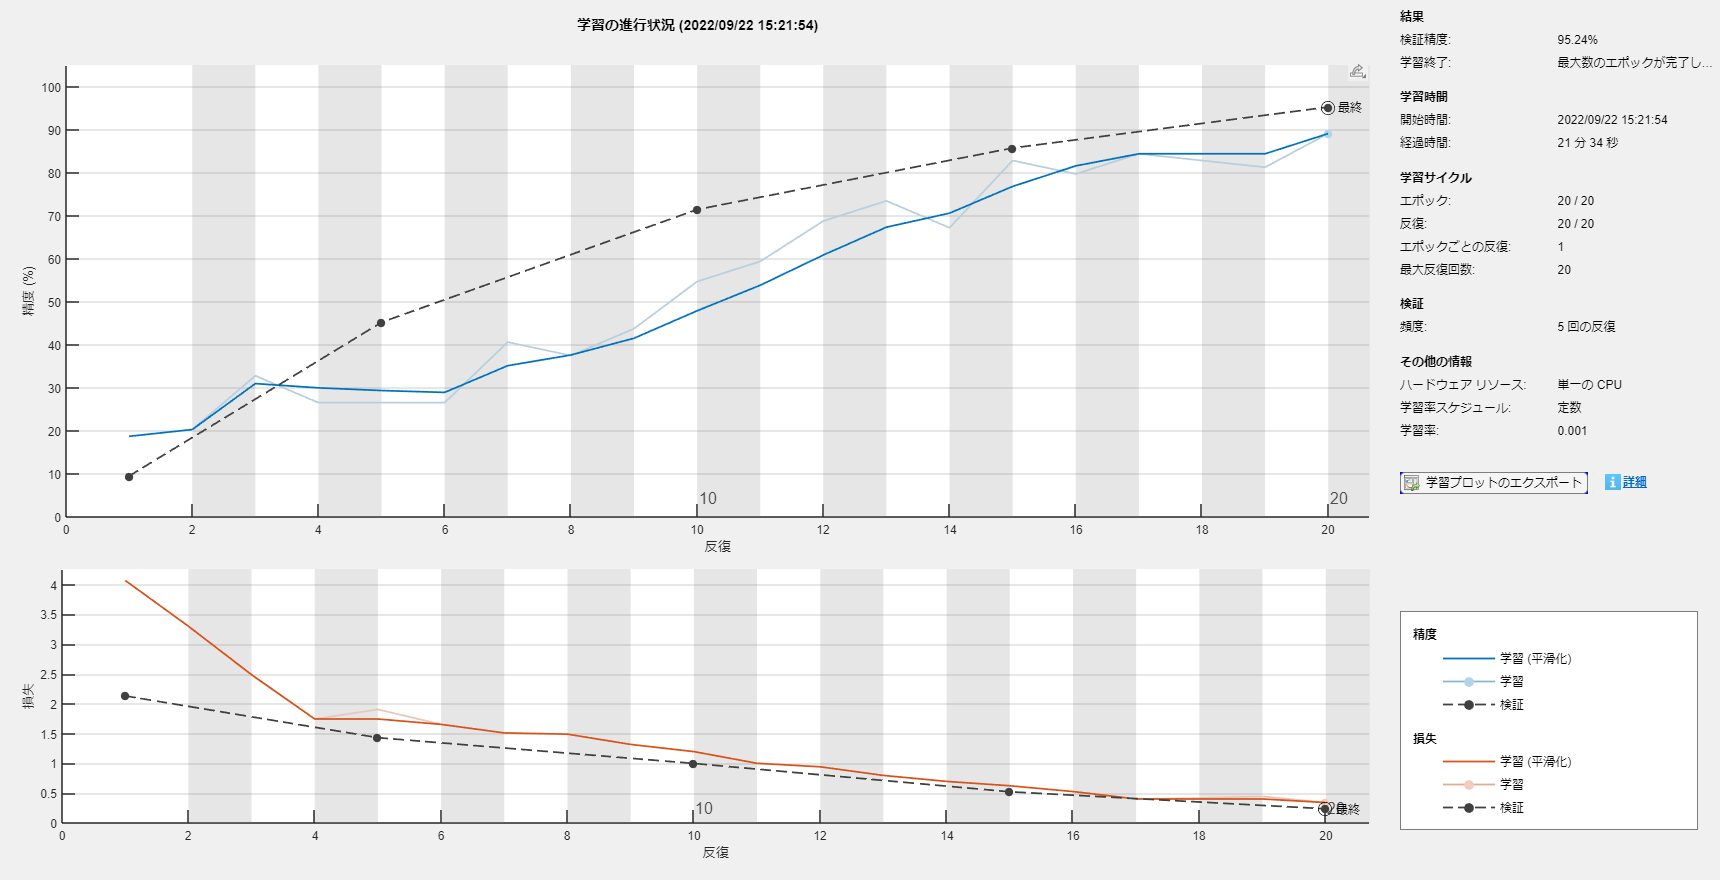

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

save('VGG16Transfer6_1.mat','net');